ORDER STATISITCS FILTER

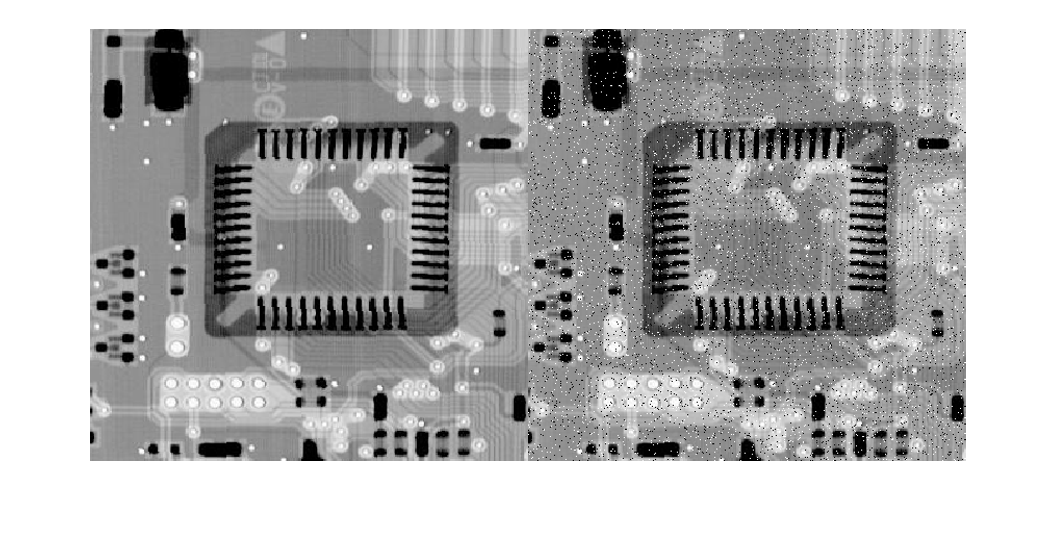

img = im2gray(imread("FigP0438(left).tif"));
noisyImg = imnoise(img,"salt & pepper");
montage({img, noisyImg})

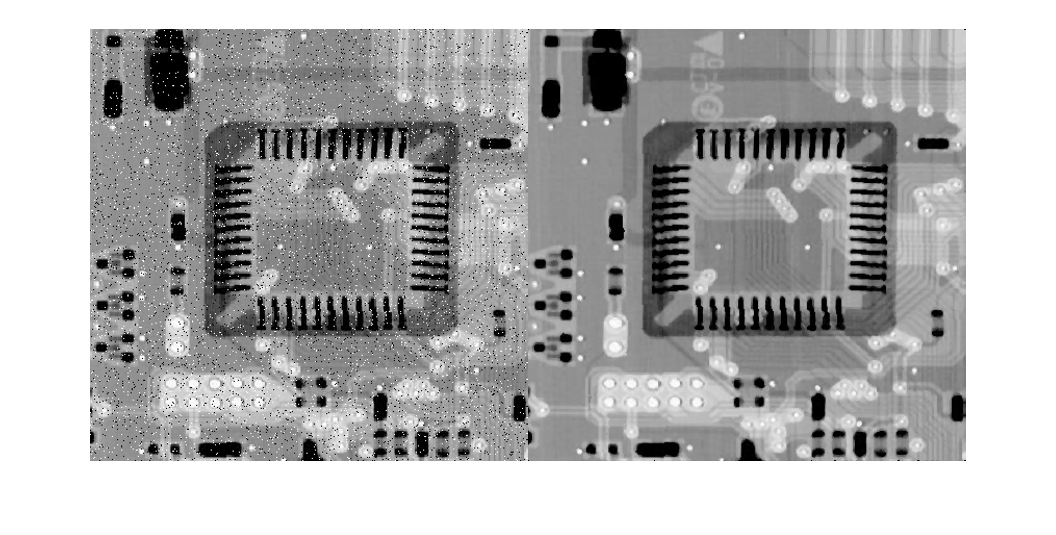

medFiltered = medfilt2(noisyImg);
montage({noisyImg, medFiltered})

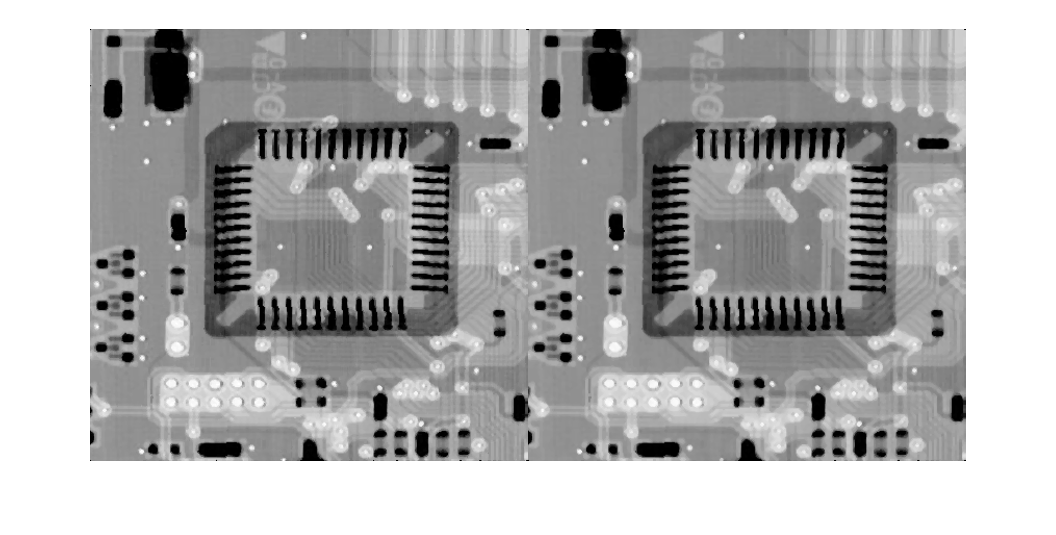

again = medfilt2(medFiltered);
montage({medFiltered, again})

USING MY FUNCTION

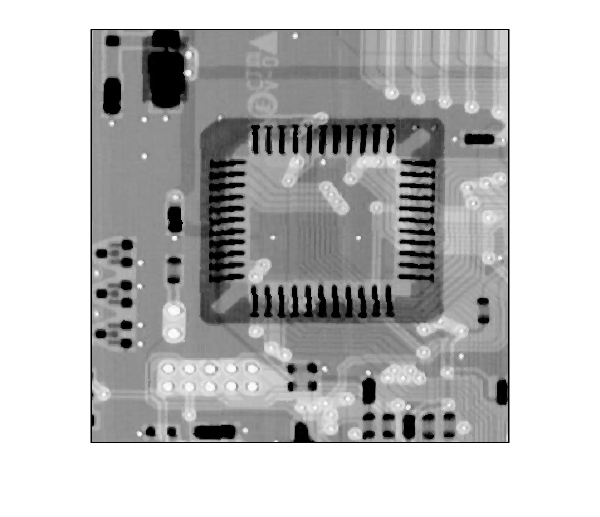

myFilterResult = applyNLFilter(noisyImg, [3 3], @median);
imshow(myFilterResult, [])

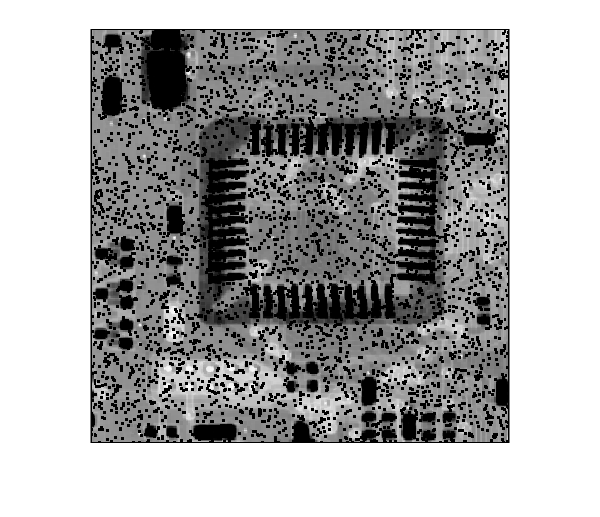

minFilterResult = applyNLFilter(noisyImg, [3 3], @min);
imshow(minFilterResult,[]);

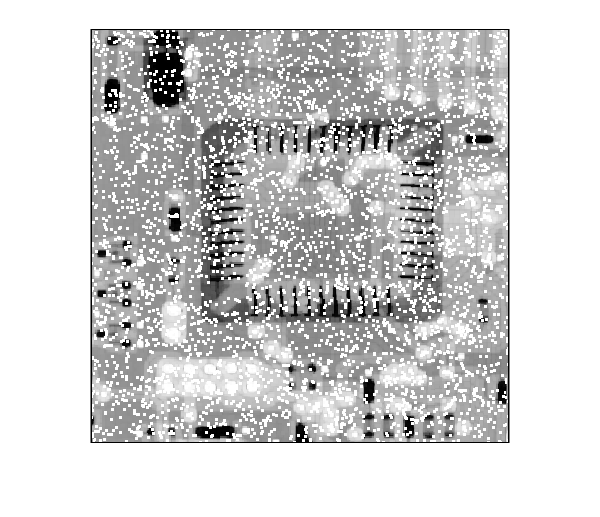

maxFilterResult = applyNLFilter(noisyImg, [3 3], @max);
imshow(maxFilterResult,[])

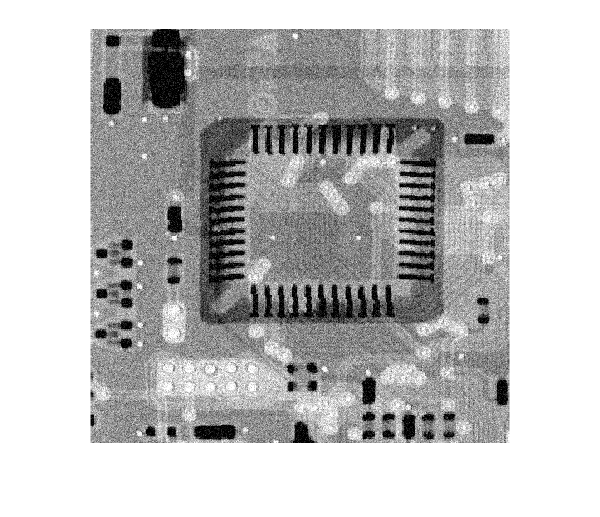

whiteNoise = imnoise(img, "gaussian");
imshow(whiteNoise);

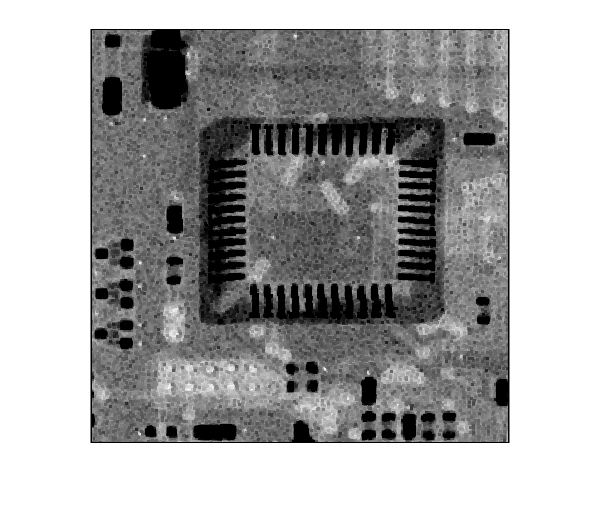

minFilterResult = applyNLFilter(whiteNoise,[3 3], @min);
imshow(minFilterResult,[]);